## ルールの設定

rules = fliplr([0 0 0 1 1 1 1 0]);

## 初期状態

N = 100;
M = zeros(N,2*N+1);
M(1,N+1) = 1;

## カーネル(?)の定義

A = 1:3;
B = (2:2*N)-2;
C = 2.^A./2;
D = A+B';

## 演算

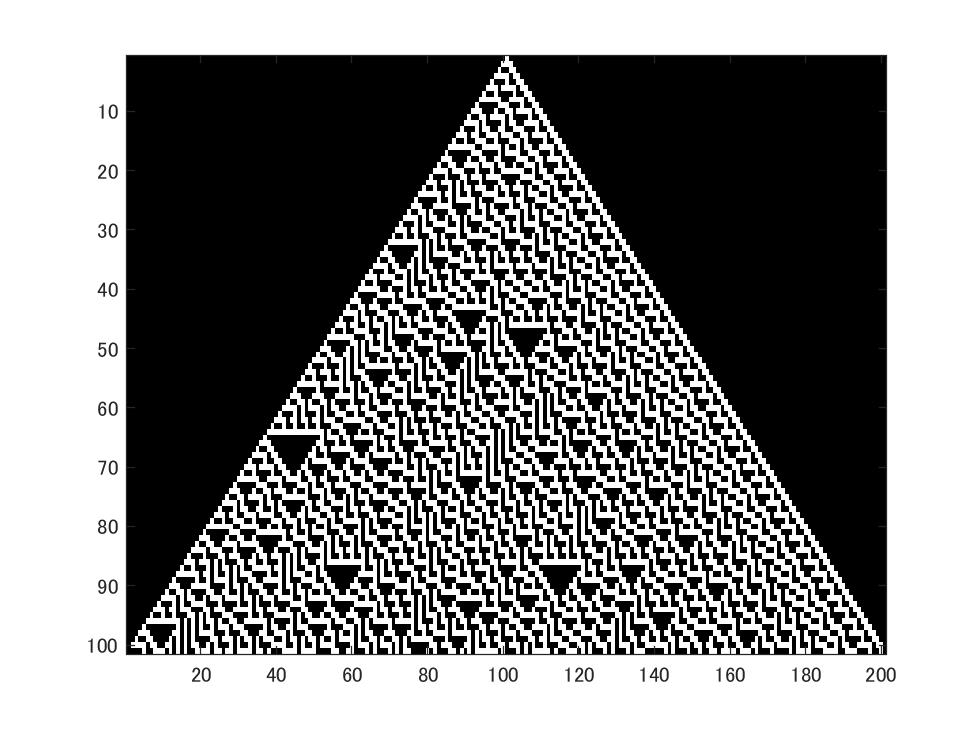

for n = 1:N 
    M(n+1,:) = [0, rules((reshape(M(n,D),size(D))*C')+1), 0];
end
imagesc(M);
colormap("gray");